In this demo, we set the flow velocity to be 6, where the pipe system is under flutter. We construct a 2D unstable SSM around the unstable straight configuration. We expect there exists a stable limit cycle on the SSM. Under the addition of external control input at the free end, we are concerned with 

[1] M. Li, H. Yan, L. Wang: Nonlinear model reduction for a cantilevered pipe conveying fluid: A system with asymmetric damping and stiffness matrices. MSSP. 2023. [https://doi.org/10.1016/j.ymssp.2022.109993](https://doi.org/10.1016/j.ymssp.2022.109993)

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

% clear all;clc;
nmodes = 4;
fcload = 1;
flowspeed = 6;
miu = 0;
Gamma=0;
alpha=0.001;
beta=0.2;
[M, C, K, fnl, fext] = build_model(nmodes,flowspeed,beta,miu,Gamma,alpha,'clamped-free','nonlinear_damp');

Getting linear and nonlinearity coefficients
Loaded coefficients from storage


n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)

Create dynamical system 

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex')
set(DS.Options,'RayleighDamping',false)

[V,D,W] = DS.linear_spectral_analysis();


 The first 8 nonzero eigenvalues are given as 
   1.0e+02 *
   0.0076 + 0.1353i
   0.0076 - 0.1353i
  -0.0704 + 0.4747i
  -0.0704 - 0.4747i
  -0.1225 + 0.0190i
  -0.1225 - 0.0190i
  -0.1240 + 1.0973i
  -0.1240 - 1.0973i


Choose Master subspace (perform resonance analysis)

We take the pair of unstable modes as the master subspace and compute the corresponding 2D unstable SSM

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
order = 9;
resonant_modes = [1,2]; 
S.choose_E(resonant_modes);

sigma_out = -16
sigma_in = -16


[W0,R0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.77E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.14E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.44E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.12E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 4.69E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 5.77E-02 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 6.72E-02 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 8.30E-02 MB


%% Reduced dynamics in symbolic form
lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = true;
options.numDigits = 4;
y = reduced_dynamics_symbolic(lamdMaster,R0,options)

$$y = \left(\begin{array}{c} 0.009578\,{\rho_{1}}^{9}+0.00558\,{\rho_{1}}^{7}-0.05442\,{\rho_{1}}^{5}-1.006\,{\rho_{1}}^{3}+0.7631\,\rho_{1}\\ 0.009245\,{\rho_{1}}^{8}+0.047\,{\rho_{1}}^{6}+0.1781\,{\rho_{1}}^{4}+0.5574\,{\rho_{1}}^{2}+13.53 \end{array}\right)$$

we indeed see a converged root, which indicates that the system has isola under the addition of forcing. In addition, cubic approximation presents analytical prediction of the critical value of forcing amplitude for the merging of main and isola branches.

% phiend = zeros(n,1);
lamda  = zeros(n,1);
lamda(1)=1.8751040687119611664453082410782141625701117335311;
lamda(2)=4.6940911329741745764363917780198120493898967375458;
lamda(3)=7.8547574382376125648610085827645704578485419292300;
lamda(4)=10.995540734875466990667349107854702939612972774652;
lamda(5)=14.137168391046470580917046812551772068603076792975;
lamda(6)=17.278759532088236333543928414375822085934519635550;
lamda(7)=20.420352251041250994415811947947837046137288894544;
lamda(8)=23.561944901806443501520253240198075517031265990051;
m = 100;
x_shapes = linspace(0,1,m);
phi_x  = cell(n,1);
for j = 1:m
    x    = x_shapes(j);
    for k=1:n
       % x    = 1;
       phin = cos(lamda(k)*x)-cosh(lamda(k)*x)-(cos(lamda(k))+cosh(lamda(k)))/(sin(lamda(k))+sinh(lamda(k)))*...
            (sin(lamda(k)*x)-sinh(lamda(k)*x));%clamped-free
       phi_x{j}(k) = phin;
       % phiend(k) = phin;
    end
end
phiend = phi_x{end}';
% disp at the free end
obsfun = @(x,mapx,nmodes) mapx*x(1:nmodes,:);
obs = @(x) obsfun(x,phiend',n);

### Transient response prediction

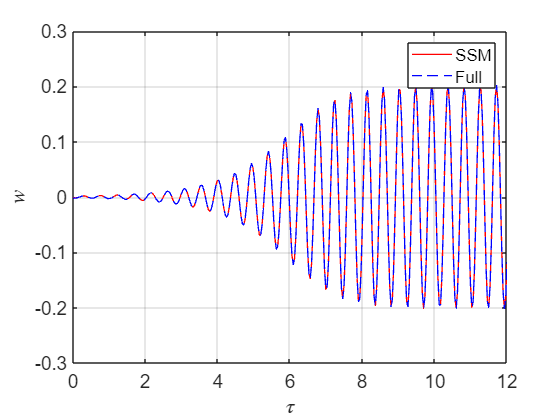

tf     = 12; % <=8 is fine
nsteps = 333;
z0     = 0.0*V(:,1); % initial condition (here we select it based on the modal shapes)
z0(1)  = 0.001;
outdof = 1:2*n;
set(DS,'u',[]);
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, outdof, z0);
[tInt,zInt] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z0);
figure;
plot(traj.time,traj.phy(:,1:n)*phiend,'r-','LineWidth',1); hold on
plot(tInt,zInt(:,1:n)*phiend,'b--','LineWidth',1);
xlabel('$\tau$','Interpreter',"latex",'FontSize',14);
ylabel('$w$','Interpreter',"latex",'FontSize',14);
set(gca,'FontSize',14); grid on
legend('SSM','Full')
xlim([0,min(traj.time(end),tInt(end))]);

### Stablization via LQR control

auData = construct_autoData(DS, resonant_modes, R0);
tf     = 6;
tspan  = linspace(0,tf,nsteps);
cont   = struct();
cont.Q    = zeros(2*n);
cont.Rhat = 0.1*(phiend'*phiend);
cont.Mhat = 1e4*eye(2*n)*(phiend'*phiend); % 1e4

Bext     = phiend;
epsilon  = 1e-3;
set(DS,'D',Bext,'epsilon',epsilon);
set(DS.Options, 'outDOF', outdof);

**ROM-based open loop control**

traj_open   = LQR_open_loop(DS,z0,'nonlinear',tspan,auData,W0,resonant_modes,1:2,cont); % 1:8 warning message

pl
  -0.0005 - 0.0062i
  -0.0005 + 0.0062i
Call fminunc to find the projection of point on SSM
approx error
   3.1398e-05
approx error
   3.1398e-05
approx error
   3.1398e-05
approx error
   2.8169e-04
approx error
   2.8169e-04
approx error
   2.8169e-04
approx error
   5.6679e-06
approx error
   5.6679e-06
approx error
   5.6680e-06
approx error
   4.5681e-06
approx error
   4.5681e-06
approx error
   4.5682e-06
approx error
   9.5513e-07
approx error
   9.5513e-07
approx error
   9.5513e-07
Time for solving optimization problem is 8.094216e-01 
p0
   1.0e-03 *
   0.1908 - 0.3644i
   0.1908 + 0.3644i
V
   0.0227 + 0.0497i   0.0227 - 0.0497i
  -0.0171 + 0.0070i  -0.0171 - 0.0070i
   0.0014 - 0.0008i   0.0014 + 0.0008i
   0.0002 - 0.0003i   0.0002 + 0.0003i
  -0.6552 + 0.3448i  -0.6552 - 0.3448i
  -0.1078 - 0.2264i  -0.1078 + 0.2264i
   0.0118 + 0.0188i   0.0118 - 0.0188i
   0.0042 + 0.0031i   0.0042 - 0.0031i
     8     2


**ROM-based closed loop control**

traj_closed = LQR_closed_loop(DS,z0,'nonlinear',tspan,auData,W0,resonant_modes,1:2,cont);

pl
  -0.0005 - 0.0062i
  -0.0005 + 0.0062i
Call fminunc to find the projection of point on SSM
approx error
   3.1398e-05
approx error
   3.1398e-05
approx error
   3.1398e-05
approx error
   2.8169e-04
approx error
   2.8169e-04
approx error
   2.8169e-04
approx error
   5.6679e-06
approx error
   5.6679e-06
approx error
   5.6680e-06
approx error
   4.5681e-06
approx error
   4.5681e-06
approx error
   4.5682e-06
approx error
   9.5513e-07
approx error
   9.5513e-07
approx error
   9.5513e-07
Time for solving optimization problem is 3.643380e-02 
p0
   1.0e-03 *
   0.1908 - 0.3644i
   0.1908 + 0.3644i
历时 0.183550 秒。
历时 0.067422 秒。
Time for backward simulation of Riccati ODE is 6.879110e-02
历时 0.285714 秒。
Time for backward simulation of compensated ODE is 2.872928e-01
历时 0.298051 秒。
Time for forward simulation of ODEs for modal coordinates is 2.994729e-01


**Full dynamics simulation - without control**

om = 2*pi/tf;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

**Full dynamics simulation - with control**

ufun = @(t) transpose(interp1(traj_open.time,traj_open.ut',t));
set(DS,'u',ufun);
[tfullwc, xfullwc] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

#### Reduced dynamics simulation - with obtained control

% traj2 = comp_transient_with_arbitrary_forcing(DS,z0,'nonlinear',tspan,auData,W_0,modes,1:10);

### Comparison with full dynamics

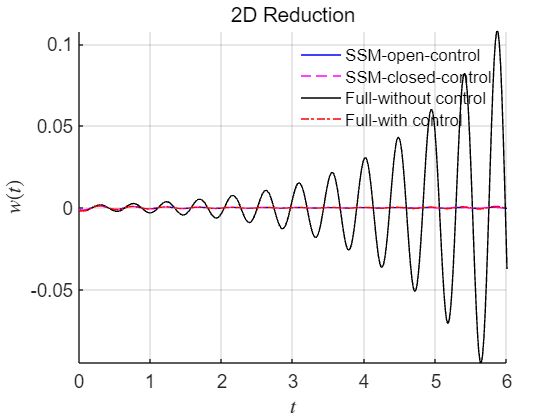

figure; hold on
plot(traj_open.time, phiend'*traj_open.zt(1:4,:),'b-','DisplayName','SSM-open-control');
plot(traj_closed.time, phiend'*traj_closed.zt(1:4,:),'m--','DisplayName','SSM-closed-control');
% plot(traj2.time, traj2.z(1,:),'g:','DisplayName','SSM-red-control');
plot(tfullwo, xfullwo(:,1:4)*phiend,'k-','DisplayName', 'Full-without control');
plot(tfullwc, xfullwc(:,1:4)*phiend,'r-.','DisplayName', 'Full-with control');
legend('show'); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$w(t)$');
ylabel(zk,'Interpreter','latex');
title('2D Reduction')
set(gca,'FontSize',14);
grid on, axis tight

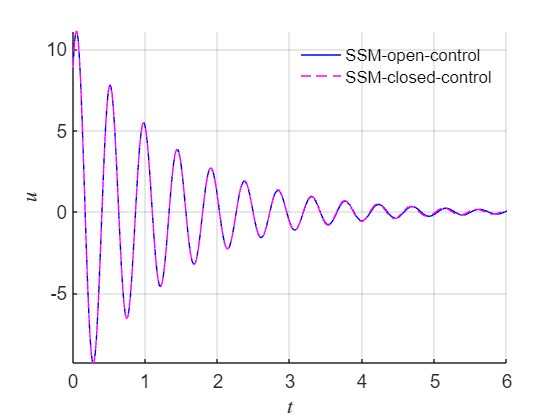

figure; hold on;
plot(traj_open.time,traj_open.ut(1,:),'b-','DisplayName','SSM-open-control');
plot(traj_closed.time,traj_closed.ut(1,:),'m--','DisplayName','SSM-closed-control');
xlabel('$t$','Interpreter',"latex")
ylabel('$u$','Interpreter','latex')
legend('show'); legend boxoff
set(gca,'FontSize',14); grid on, axis tight

### Repeat the above procedure but with a different initial condition. Here we take a point on the limit cycle as the initial condition to demonstrate the stabilization in nonlinear regime.

% we take the state at t=10 as the initial time to apply control
[~,idx] = min(abs(tInt-10));
tf      = 1.5;
tspan   = linspace(0,tf,10000);
z02     = zInt(idx,:)';

cont   = struct();
cont.Q    = 1e4*eye(2*n)*(phiend'*phiend);
cont.Rhat = 0.001*(phiend'*phiend);
cont.Mhat = 1e4*eye(2*n)*(phiend'*phiend); % 1e4

## Cut-off Criteria

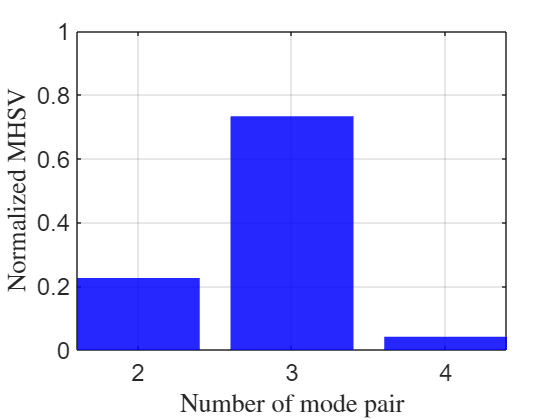

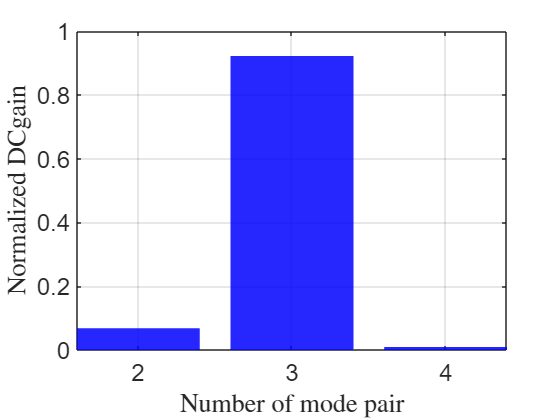

res = Cutof_LQR_closed_loop_MT2_comp(DS,4,phiend);

**ROM-based open loop control**

% traj_open2   = LQR_open_loop(DS,z02,'nonlinear',tspan,auData,W0,resonant_modes,1:6,cont); % 1:8 warning message

## **Close loop**


% traj_closed2 = LQR_closed_loop(DS,z02,'nonlinear',tspan,auData,W0,resonant_modes,[1,2,5,6],cont);
% % traj_closed2   = LQR_closed_loop_MT2(DS,z02,'nonlinear',tspan,auData,W0,resonant_modes,2,cont);
% % % % traj_closed2 = LQR_closed_loop_MT(DS,z02,'nonlinear',tspan,auData,W0,resonant_modes,1:3,cont);
% om = 2*pi/tf;
% set(DS,'u',[]);
% [tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','ode45','outdof',outdof,'init',z02);
% 
% 
% 
% ufun = @(t) transpose(interp1(traj_closed2.time,traj_closed2.ut',t));
% set(DS,'u',ufun);
% [tfullwc, xfullwc] = time_integration_transient(DS,om,'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','ode45','outdof',outdof,'init',z02);
% 
% 
% figure; hold on
% % % plot(traj_open2.time, phiend'*traj_open2.zt(1:4,:),'b-','DisplayName','SSM-open-control');
% plot(traj_closed2.time, phiend'*traj_closed2.zt(1:4,:),'m--','DisplayName','SSM-closed-control');
% % % plot(traj2.time, traj2.z(1,:),'g:','DisplayName','SSM-red-control');
% plot(tfullwo, xfullwo(:,1:4)*phiend,'k-','DisplayName', 'Full-without control');
% plot(tfullwc, xfullwc(:,1:4)*phiend,'r-.','DisplayName', 'Full-with control');
% legend('show'); legend boxoff
% xlabel('$t$','Interpreter',"latex")
% zk = strcat('$w(t)$');
% ylabel(zk,'Interpreter','latex');
% title('2D Reduction')
% set(gca,'FontSize',14);
% grid on, axis tight

% figure; hold on;
% % plot(traj_open2.time,traj_open2.ut(1,:),'b-','DisplayName','SSM-open-control');
% plot(traj_closed2.time,traj_closed2.ut(1,:),'m--','DisplayName','SSM-closed-control');
% xlabel('$t$','Interpreter',"latex")
% ylabel('$u$','Interpreter','latex')
% legend('show'); legend boxoff
% set(gca,'FontSize',14); grid on, axis tight

## Moving window


ts = [0 0.4 1 1.5];

om = 2*pi/ts(end);
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z02);

% ts = [0, 0.2, 0.6, 1];
nint = numel(ts)-1;
xf = z02;
trajs = cell(nint,1); tfullc = cell(nint,1); xfullc = cell(nint,1);

% the number of linear modes is very important - to follow
for k=1:nint
    ta = ts(k); tb = ts(k+1);
    tspan = linspace(ta,tb,nsteps);
    traj   = LQR_closed_loop(DS,xf,'linear',tspan,auData,W0,resonant_modes,[1,2,5,6],cont);
    % traj   = LQR_closed_loop(DS,xf,'nonlinear',tspan,auData,W0,resonant_modes,[1,2,5,6],cont);
    ufun  = @(t) transpose(interp1(traj.time,traj.ut',t));
    set(DS,'u',ufun);
    [tk, xk,xkf] = time_integration_transient(DS,2*pi/(tb-ta),'nCycles',...
        1, 'nSteps', nsteps,...
        'integrationMethod','ode15s','outdof',outdof,'init',xf,'ts',ta);
    % update initial condition
    xf = xkf';
    % record results
    trajs{k}  = traj;
    tfullc{k} = tk;
    xfullc{k} = xk;
end

pl
  -0.8455 - 0.0813i
  -0.8455 + 0.0813i
p0
  -0.8455 - 0.0813i
  -0.8455 + 0.0813i
历时 0.026815 秒。
历时 0.033618 秒。
Time for backward simulation of Riccati ODE is 3.407160e-02
历时 0.123050 秒。
Time for backward simulation of compensated ODE is 1.249643e-01
历时 0.153397 秒。
Time for forward simulation of ODEs for modal coordinates is 1.546357e-01
pl
  -0.1650 + 0.3473i
  -0.1650 - 0.3473i
p0
  -0.1650 + 0.3473i
  -0.1650 - 0.3473i
历时 0.025670 秒。
历时 0.018436 秒。
Time for backward simulation of Riccati ODE is 1.869870e-02
历时 0.151750 秒。
Time for backward simulation of compensated ODE is 1.534581e-01
历时 0.171933 秒。
Time for forward simulation of ODEs for modal coordinates is 1.732000e-01
pl
  -0.0712 - 0.0228i
  -0.0712 + 0.0228i
p0
  -0.0712 - 0.0228i
  -0.0712 + 0.0228i
历时 0.019484 秒。
历时 0.011213 秒。
Time for backward simulation of Riccati ODE is 1.144390e-02
历时 0.129178 秒。
Time for backward simulation of compensated ODE is 1.308547e-01
历时 0.140544 秒。
Time for forward simulation of ODEs for mo

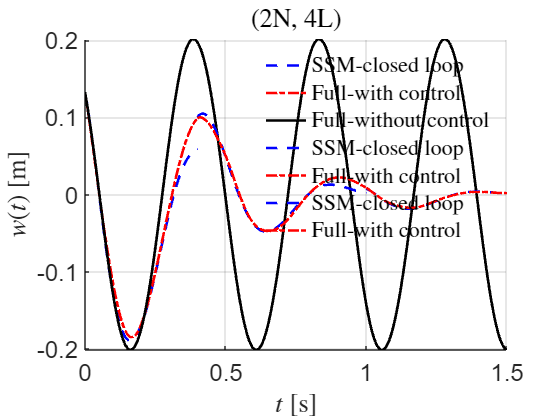


figure; hold on


plot(trajs{1}.time, phiend'*trajs{1}.zt(1:4,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);

plot(tfullc{1}, xfullc{1}(:,1:4)*phiend,'r-.','DisplayName','Full-with control','LineWidth',2);

plot(tfullwo, xfullwo(:,1:4)*phiend,'k-','DisplayName','Full-without control','LineWidth',2);
plot(trajs{2}.time, phiend'*trajs{2}.zt(1:4,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullc{2}, xfullc{2}(:,1:4)*phiend,'r-.','DisplayName','Full-with control','LineWidth',2);
plot(trajs{3}.time, phiend'*trajs{3}.zt(1:4,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullc{3}, xfullc{3}(:,1:4)*phiend,'r-.','DisplayName','Full-with control','LineWidth',2);

xlabel('$t$ [s]','Interpreter',"latex")
zk = strcat('$w(t)$ [m]');
ylabel(zk,'Interpreter','latex');
legend('show','Interpreter','latex')
legend boxoff
title('(2N, 4L)','Interpreter','latex')
set(gca,'FontSize',18);
grid on, axis tight

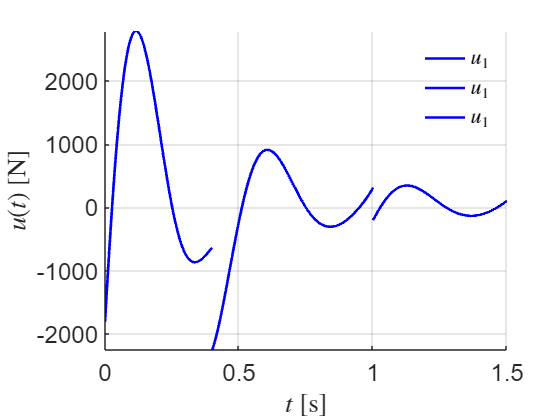

figure; hold on
for k=1:nint
    plot(trajs{k}.time, trajs{k}.ut(1,:),'b-','DisplayName','$u_1$','LineWidth',2);
end
legend('show','Interpreter','latex')
legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [N]','Interpreter','latex');
set(gca,'FontSize',18);
grid on, axis tight

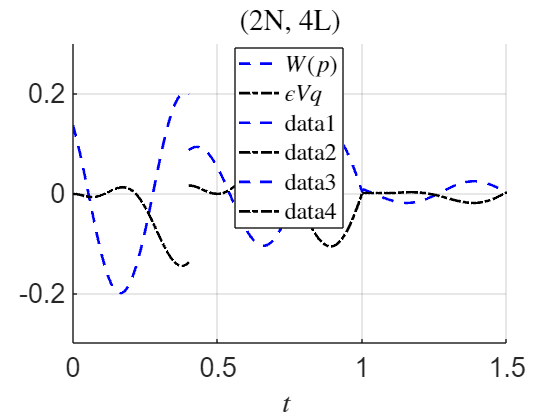

% load("traj3.mat","traj3")
% load("traj4.mat","traj4")
% load("traj5.mat","traj5")

traj3 = trajs{1};
traj4 = trajs{2};
traj5 = trajs{3};

figure; hold on
% tt = [traj3.time, traj4.time];
% zt = [traj3.zt, traj4.zt];
% zauto = [traj3.zt_auto, traj4.zt_auto];
% ep_Vq = zt - zauto;

plot(traj3.time,  phiend'*traj3.zt_auto(1:4,:),'b--','DisplayName','$W(p)$','LineWidth',2);
plot(traj3.time, phiend'*(traj3.zt(1:4,:)-traj3.zt_auto(1:4,:)),'k-.','DisplayName','$\epsilon Vq$','LineWidth',2);

plot(traj4.time, phiend'*traj4.zt_auto(1:4,:),'b--','LineWidth',2);
plot(traj4.time, phiend'*(traj4.zt(1:4,:)-traj4.zt_auto(1:4,:)),'k-.','LineWidth',2);

plot(traj5.time, phiend'*traj5.zt_auto(1:4,:),'b--','LineWidth',2);
plot(traj5.time, phiend'*(traj5.zt(1:4,:)-traj5.zt_auto(1:4,:)),'k-.','LineWidth',2);

legend('show','Interpreter',"latex",'Location','best'); legend boxoff
xlabel('$t$ ','Interpreter',"latex")
% zk = strcat('$z_{',num2str(outdof(1)),'}(t)$');
% ylabel(zk,'Interpreter','latex');
title('(2N, 4L)', 'Interpreter','latex')
set(gca,'FontSize',20);
grid on
% axis tight
legend boxon
print(gcf, 'ShellIRs_z(t)_Factorization.png', '-dpng','-r300');

## Moving window - v2 - full_Lin

% ts = 0:0.2:1.0;
% nint = numel(ts)-1;
% xf = z02;
% trajs = cell(nint,1); tfullc = cell(nint,1); xfullc = cell(nint,1);
% % the number of linear modes is very important - to follow
% for k=1:nint
%     ta = ts(k); tb = ts(k+1);
%     tspan = linspace(ta,tb,nsteps);
%     traj   = LQR_closed_loop_full_Lin(DS,xf,'nonlinear',tspan,auData,W0,resonant_modes,cont);
%     ufun  = @(t) transpose(interp1(traj.time,traj.ut',t));
%     set(DS,'u',ufun);
%     [tk, xk,xkf] = time_integration_transient(DS,2*pi/(tb-ta),'nCycles',...
%         1, 'nSteps', nsteps,...
%         'integrationMethod','ode15s','outdof',outdof,'init',xf,'ts',ta);
%     % update initial condition
%     xf = xkf';
%     % record results
%     trajs{k}  = traj;
%     tfullc{k} = tk;
%     xfullc{k} = xk;
% end

### Comparison with full dynamics

% figure; hold on
% for k=1:nint
%     plot(trajs{k}.time, phiend'*trajs{k}.zt(1:4,:),'r-');
%     plot(tfullc{k}, xfullc{k}(:,1:4)*phiend,'b-');
% end
% plot(tfullwo, xfullwo(:,1:4)*phiend,'k-');
% xlabel('$t$','Interpreter',"latex")
% zk = strcat('$w(t)$');
% ylabel(zk,'Interpreter','latex');
% title('2D Reduction')
% set(gca,'FontSize',14);
% grid on, axis tight

% figure; hold on
% for k=1:nint
%     plot(trajs{k}.time, trajs{k}.ut(1,:),'DisplayName','SSM-control');
% end


## Draw

% xfull  =  [xfullc{1}(:,1:4); xfullc{2}(:,1:4); xfullc{3}(:,1:4)];
% z_shapes = zeros(size(xfull,1), m);
% 
% for j = 1:m
%     z_shapes(:,j) = xfull * phi_x{j}';
% end
% 
% hFig = figure('Position', [0, 0, 800, 400]);
% hold on;
% % xticks(0:300:2700)
% % yticks(-2:1.0:6)
% xlim([0,1])
% ylim([min(z_shapes(:)),max(z_shapes(:))])
% xlabel("x/mm")
% ylabel("z/mm")
% box on;  % 显示所有坐标轴
% n = size(z_shapes,1);
% for i = 1:n
%     % z_interpolated = interp1(xt(i,:), [zt(i,:), z_prime(i,:)], x_val, 'spline', 'extrap');
%     beamDisplacement = plot(x_shapes, z_shapes(i,:), 'b-');
%     beamsca = scatter(x_shapes, z_shapes(i,:), 'ko');
%     drawnow
%     frame = getframe(gcf);
%     imwrite(frame.cdata, ['frame' num2str(i, '%03d') '.png']);
%     delete(beamDisplacement);
%     delete(beamsca)
% end
% close(hFig)


% clear all
% clc
% 
% % 3D Beam
% load("x_shapes.mat","x_shapes")
% load("z_shapes.mat","z_shapes")
% load("tfullc.mat","tfullc")
% load("xfullc.mat","xfullc")
% load("phiend.mat","phiend")
% load("trajs.mat","trajs")
% load("xfullwo.mat","xfullwo")
% load("tfullwo.mat","tfullwo")
% 
% tt = [tfullc{1};tfullc{2};tfullc{3}];
% xfulls = [xfullc{1}(:,1:4); xfullc{2}(:,1:4); xfullc{3}(:,1:4)]* phiend;
% ttSSM  = [trajs{1}.time, trajs{2}.time, trajs{3}.time];
% xSSM   = phiend'*[trajs{1}.zt(1:4,:), trajs{2}.zt(1:4,:), trajs{3}.zt(1:4,:)];
% 
% xfullwo = xfullwo(:,1:4) * phiend;
% 
% h=0.08;                                   %Height of beam [mm]
% b=0.08; 
% % facesHead = [1 2 3 4;...
% %              1 2 6 5;...
% %              4 3 7 8;...
% %              1 5 8 4;...
% %              2 6 7 3];
% % 
% % facesTail = [1 2 6 5;...
% %              4 3 7 8;...
% %              1 5 8 4;...
% %              2 6 7 3];
% % 
% % facesBody = [1 2 6 5;...
% %              4 3 7 8;...
% %              1 5 8 4;...
% %              2 6 7 3];
% 
% faces = [1 2 3 4;...
%          5 6 7 8;...
%          1 2 6 5;...
%          4 3 7 8;...
%          1 5 8 4;...
%          2 6 7 3];
% patchcolor = '#F08918';
% patchcolor2 = [1, 0.54, 0.094];
% % linecolor  = [1, 0.4, 0.00];
% linecolor  = [0.1, 0.1, 0.1];
% linewid    = 1;
% factor = 1;
% position = [0,0,800,700]
% for k = 1:5:999
%     % hfig = figure([1,1,1000,600]);
%     hfig = figure('Position',position);
%     hold on;
% % axis equal;
%     s1 = subplot(2,1,1);
%     hold on
% 
%     scatter(tt(k), xfulls(k),[], patchcolor2,'filled', 'LineWidth', 10, 'DisplayName','Current state');
%     plot(ttSSM, xSSM,'b--','DisplayName','SSM-closed loop','LineWidth',1.2);
%     plot(tfullwo, xfullwo,'k-','DisplayName', 'Full-without control','LineWidth',1.2);
%     plot(tt, xfulls,'m-.','DisplayName', 'Full-with control','LineWidth',1.2);
% 
%     drawnow
%     % xlim([0,1.5])
%     ylim([-0.25,0.35])
%     % daspect([0.7 1 1]); 
%     legend('show','Interpreter','latex'); legend boxoff
%     xlabel('$t$','Interpreter',"latex")
%     zk = strcat('$w(t)$');
%     ylabel(zk,'Interpreter','latex');
%     title('(2N, 4L)','Interpreter','latex')
%     set(gca,'FontSize',20);
%     grid on;
% 
% 
%     x_val = x_shapes;
%     z_val = z_shapes(k,:);
%     vertices = cell(length(x_val)-1,1);
%     for i = 1:length(x_val)-1
%         pi     = [x_val(i),0,z_val(i)];
%         pip1   = [x_val(i+1),0,z_val(i+1)];
%         vertices{i} = MidPoints2Vertices2Ddeform(pi,pip1,b,h,factor);
%     end
% 
%     s2 = subplot(2,1,2);
%     hold on
% 
%     % patch('Faces',facesHead,'Vertices',vertices{1},'FaceColor',patchcolor,'EdgeColor','none')
%     plot3([vertices{1}(1:4,1);vertices{1}(1,1)],[vertices{1}(1:4,2);vertices{1}(1,2)],[vertices{1}(1:4,3);vertices{1}(1,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%     for i = 1:length(x_val)-1
%         % fill3(vertices(faces, 1), vertices(faces, 2), vertices(faces, 3), 'b')
%         % patch('Vertices',vertices,'Face',faces,'Facecolor','b');
%         patch('Faces',faces,'Vertices',vertices{i},'FaceColor',patchcolor,'EdgeColor','none')
%         view(3);
%         plot3([vertices{i}(1,1),vertices{i}(5,1)],[vertices{i}(1,2),vertices{i}(5,2)],[vertices{i}(1,3),vertices{i}(5,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%         plot3([vertices{i}(2,1),vertices{i}(6,1)],[vertices{i}(2,2),vertices{i}(6,2)],[vertices{i}(2,3),vertices{i}(6,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%         plot3([vertices{i}(3,1),vertices{i}(7,1)],[vertices{i}(3,2),vertices{i}(7,2)],[vertices{i}(3,3),vertices{i}(7,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%         plot3([vertices{i}(4,1),vertices{i}(8,1)],[vertices{i}(4,2),vertices{i}(8,2)],[vertices{i}(4,3),vertices{i}(8,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%     end
%     plot3([vertices{end}(5:8,1);vertices{end}(5,1)],[vertices{end}(5:8,2);vertices{end}(5,2)],[vertices{end}(5:8,3);vertices{end}(5,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%     drawnow
% 
%     xlim([0,1.1])
%     ylim([-0.15,0.15])
%     zlim([-0.25,0.2])
%     grid on ;
%     xlabel('$x$','Interpreter',"latex");
%     ylabel('$y$ ','Interpreter',"latex");
%     zlabel('$z$ ','Interpreter',"latex");
%     set(gca,'FontSize',20);
%     % set(gca, 'xtick', [], 'ytick', [], 'ztick', []);
%     % daspect([12 1 1]); % 设置为立方体的比例 factor = 5
%     % view(20, 9);
% 
% 
%     daspect([1 1 1.5]); % 设置为立方体的比例
%     view(20, 13);
% 
%     % 保存每一帧，如果需要创建 GIF
%     % frame = getframe(gcf);
%     % frame = getframe(gcf);
%     % imwrite(frame.cdata, ['frame' num2str(k, '%03d') '.png']);
%     % print(gcf, ['frame' num2str(i, '%03d') '.png'], '-dpng');
%     print(gcf, ['res' num2str(k, '%03d') '.png'], '-dpng','-r300');
% 
%     % 清除之前的位移图形
%     % close(gcf);
%     % clf
%     % delete(s1)
%     % delete(s2)
%     delete(hfig)
% 
% end